# 11. Arduino-Controlled LM317 DC Power Supply

© B. Rasnow 2 Jun 25

## Objective

Design, prototype, characterize, and validate a software-serial port controlled DC power supply. 

At the "top" level [1] of abstraction, we're seeking a MATLAB function, we might call it `setVolts(volts)` that sets our LM317 power supply to the corresponding value, thus providing an alternative to manually turning a potentiometer to control the voltage. At the "bottom" level, we have a working LM317 variable voltage regulator (controlled by a 10k potentiometer) and an Arduino which MATLAB can communicate with to 1) make DC voltages between 0 and `vref` ~ 4.5-5V, and 2) return analog time series measured on A0 and A1 at ~8900 samples/sec. 

There's a scene in the movie, "Apollo 13", where upon realizing the astronauts have to figure out how to fit a square carbon dioxide filter into a round socket (or visa versa), the mission controller calls a group of engineers into a room, throws an assortment of materials onto a table, and instructs them, "your task now is to make this (the square filter) fit into this (the round receptacle) just using this stuff". Likewise, our task now is "make 0-4.5V from the PWM filter control a 1.25-11V LM317. What do we have to work with? Resistors, capacitors, transistors ... but as you'll see, that's too limiting and low-level. A carpenter doesn't think "I have to build a house using steel and wood", but works (mentally and physically) with abstract and functional units -- nails and screws, beams and sheets, frames and walls, .... 

## Design

### How does an LM317 circuit work? 

Or more specifically, how does changing (rotating) R2 actually change the LM317 output voltage? More careful and meticulous study of the [datasheet ](https://www.st.com/resource/en/datasheet/lm317.pdf)[2] reveals this answer. But before reading on, try to explain *how* (*why*) an LM317 circuit (Fig. 1) works -- can you figure it out?

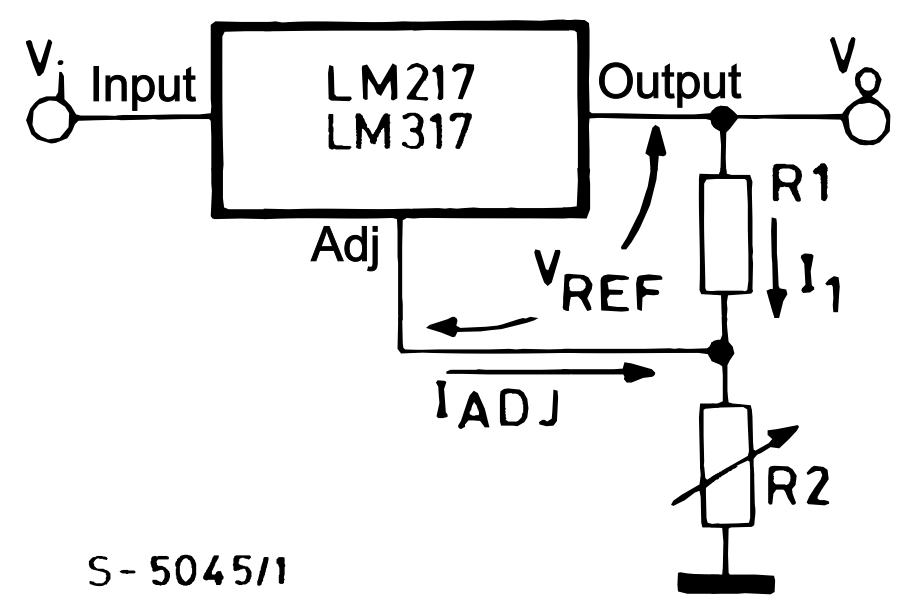 


$$V_{OUT} = V_{REF} (1 + R2/R1) + I_{ADJ} R2$$
 

        Figure 1. Basic circuit and equation from the LM317 datasheet [2].

The LM317 produces a constant reference voltage $V_{REF} = 1.25V$ between its Output and Adj pins (Fig. 1). $R1$ converts that constant voltage into a constant current, $I_1 = V_{REF} / R1 \approx 1.25V/1.3k\Omega\approx 1mA$ in our circuit. Where does that current *go*? KCL at the lower right node of Fig. 1 says $I_1+I_{ADJ} = I_2$, i.e., it flows through the control pot $R2$. Elsewhere the datasheet states $I_{ADJ} \le 50\mu A$ which is << $I_1$ so ignore it. $I_1$ flowing through $R2$ makes a voltage across $R2$, $V_{R2} = I_2 R2 \approx I_1 * R2$. The output pin is $V_{REF}$ more than this, resulting (after a little algebra) in the characteristic equation in Fig. 1. Consider the extreme values of R2: when R2 = 0 ohms, VR2 = 1mA * 0 = 0V and `Vout` = 1.25V. When R2 ~10k, VR2 ~ 1mA * 10k = 10V and `Vout` ~ 11.25V, just as we measured. 

### Current Mirror

What if we could create another, parallel or "shunt" path for $I_1$ so it wouldn't all flow through R2 and raise the output voltage by $I_1 * R2$? Recall one of the 2-transistor circuits we studied was the [current mirror](https://en.wikipedia.org/wiki/Current_mirror) [3], which has the characteristic (if Q1 and Q2 are identical -- since their bases and emitters are at the same voltages), that their collector currents will also be the same or "mirrored" -- even though the collectors might be connected to independent sources. 

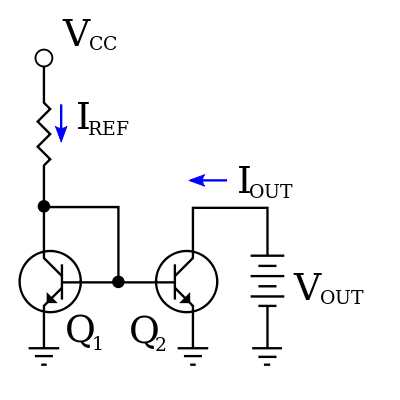

        Figure 2. A current mirror implemented with NPN  bipolar transistors using a resistor (upper left) to set the reference current $I_{REF}$ = $I_{OUT}$. From Figure 1 of [https://en.wikipedia.org/wiki/Current_mirror.](https://en.wikipedia.org/wiki/Current_mirror.) 

Imagine our filtered DC PWM voltage connected to $V_{CC}$ in Fig. 2. The voltage on the other side of $R_{REF}$ is $V_{BE}$ of $Q_1$ and $Q_2$ ~ 0.6V when they are active. Thus $I_{REF} = (V_{PWM} - 0.6V) / R_{REF} $ when the transistors are active. Replacing $V_{OUT}$ in Fig. 2 with the top of the LM317's R2 in Fig. 1 turns the variable PWM voltage into a variable shunt current bypassing R2, reducing $i_1*R2$, and lowering the LM317's output voltage. 

There is a problem. Our PWM filter can't generate $I_{REF} = 1mA$ of current at 4.5V, because it's Thevenin resistance is too high. The most current a 10K$\Omega$ resistor can deliver connected to a 4.5V source is 4.5V/10k = 0.45mA (and the 10k resistor's "output" voltage would be zero at that current), so our PWM filter is capable of generating far too little current to mirror. 

### Emitter Follower

A solution is another transistor "building block" circuit, the [emitter follower](https://en.wikipedia.org/wiki/Common_collector) [4]. 

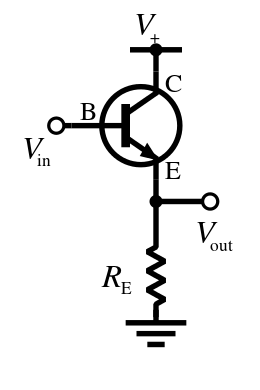

        Figure 3. Emitter follower (also know as a common collector and trans-impedance amplifier). 

In our case, $R_E = R_{REF}$ of the current mirror in Fig. 2. When the transistor is active, i.e., $V_{BE} > 0.6V$, its collector provides $\beta I_B$ of the emitter current. $V_{out} \approx V_{in} - 0.6V$ and $I_{out} = \beta I_{in}$, so $Z_{in} = \beta Z_{out}$. If $\beta \approx 200$ as we found for our S8050 or 2N2222 transistors then the PWM filter must source just 1/200mA to the emitter follower to generate 1mA of shunt through the mirror (the collector provides the other 0.998mA). This will cause a DC voltage "error" or drop across the PWM filter of 1/200mA * 12k$\Omega$ = 60mV, in addition to ~600mV drops over $V_{BE}$. PWM voltages below ~1.2V won't be enough to turn on both the emitter follower and the current mirror's transistors, thus PWM values below 1.2V*255/4.5V = 68 aren't expected to produce change in the LM317 output, but larger PWM values will, so we might expect the ability to program our power supply to > 180 different voltages. 

### Putting the pieces together

At this point we have an abstract idea that 1) an Arduino with a 2) PWM filter and 3) emitter follower can drive a 4) current mirror to control a 5) LM317 variable power supply. Our brain can (maybe) handle 5 things at once. When we now draw a schematic, the number of components gets multiplied and its easy to lose the forest for the trees. I drew this (ugly) schematic in Powerpoint, copy/pasting Figs. 1-3 above. As ugly as it is, it helps to recognize modular boundaries. I added a voltage divider on the LM317 output connected to Arduino A0 to automate validation and calibration.

        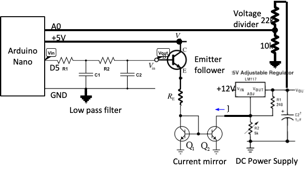

        Figure 4. A "copy/paste" schematic highlights modular design. At top right is a voltage divider reducing the output so Arduino can measure it. 

I've redrawn the schematic in Fig. 5 many times (and I encourage you to do the same). Its complexity can seem overwhelming, if you don't train your eyes to recognize the modules. Drawing boundaries around the modules might help you -- or add more clutter? Trade-offs. A carpenter might build a house with 1000 pieces of wood and 4000 nails, but that's not how they conceptualize the task. The schematic is the map we'll (try to) faithfully follow, checking off each connection as we make them on the solderless breadboard. Any schematic errors will likely become errors in the prototype circuit (along with other wiring mistakes), making debugging that much harder. Taking appropriate time, focus, and care while drawing the map will save you much debugging time. 

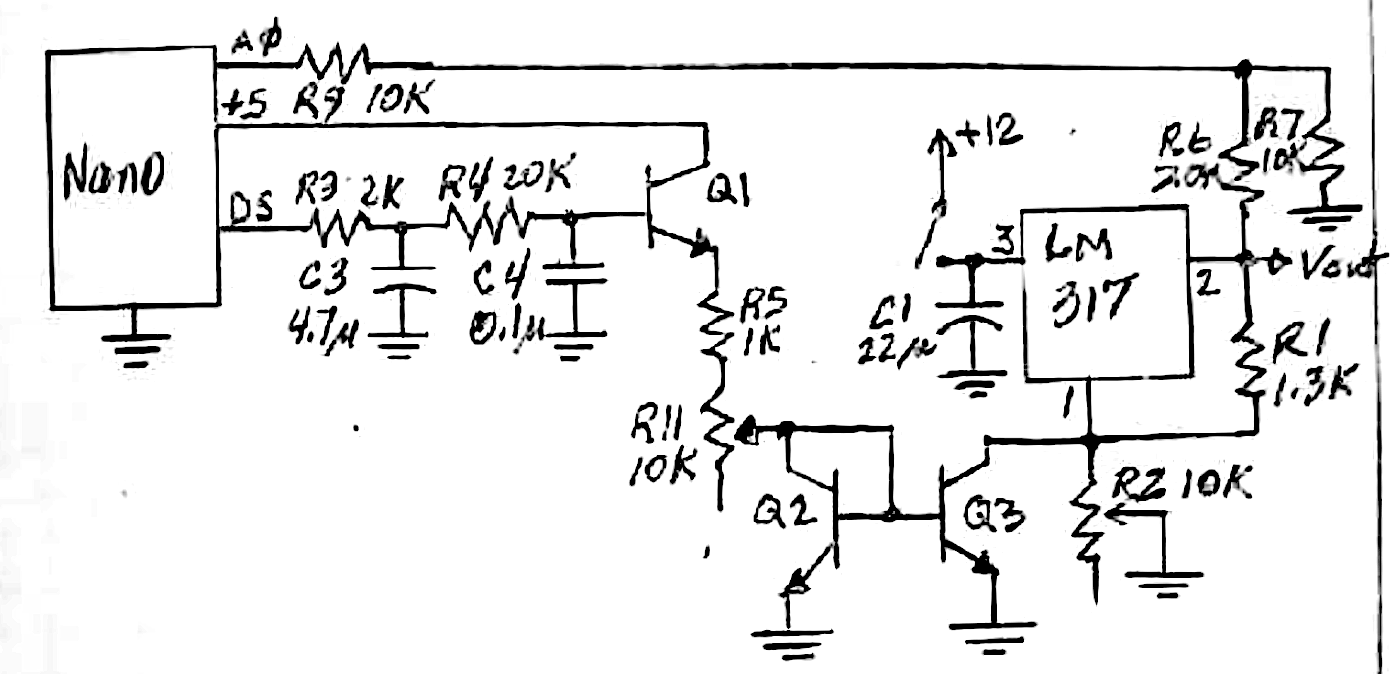

        Figure 5. A hand drawn schematic with each component (including trim pots) uniquely numbered. 

    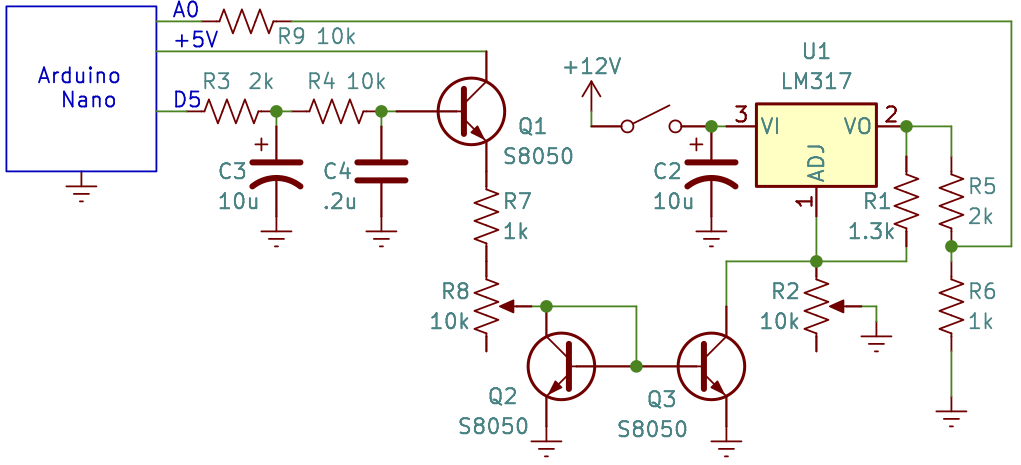

        Figure 6. Schematic drawn in Kicad. Some component numbers are different from Fig. 5, I'll refer in the rest of this document to numbering in this figure.

We haven't computed a value for $R_E$ yet. It should support a current ~ 1mA at 4.5V, so a 1k resistor in series with a 10k trim pot is a viable choice (R7-8 in Fig. 6). If the kit included a 1k pot, we'd use it with a larger series resistance, for more precise control. A mininmum value of R7 is important to limit Arduino current if R8 in Fig. 6 were adjusted toward zero. 

## Prototyping

The LM317 is already is soldered, so we just need to solder a jumper wire to shunt R2. I suggest a yellow wire for consistency. Consider soldering it at the most convenient location along the existing wires connecting R2 and and LM317-1. 

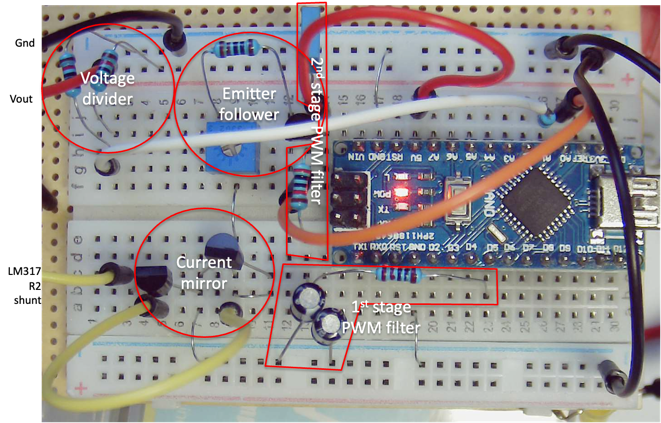

        Figure 7. Solderless breadboard prototype. Arduino's A0 = filtered PWM output, A1 = voltage divided LM317 output (through a 10k series resistor soldered to the white jumper -- for additional current-limiting protection).

### Testing

Set the LM317's R2 pot to the maximum voltage. MATLAB can set a range of PWM values and measure the resulting voltages. Adding short pauses may improve stability on your system.

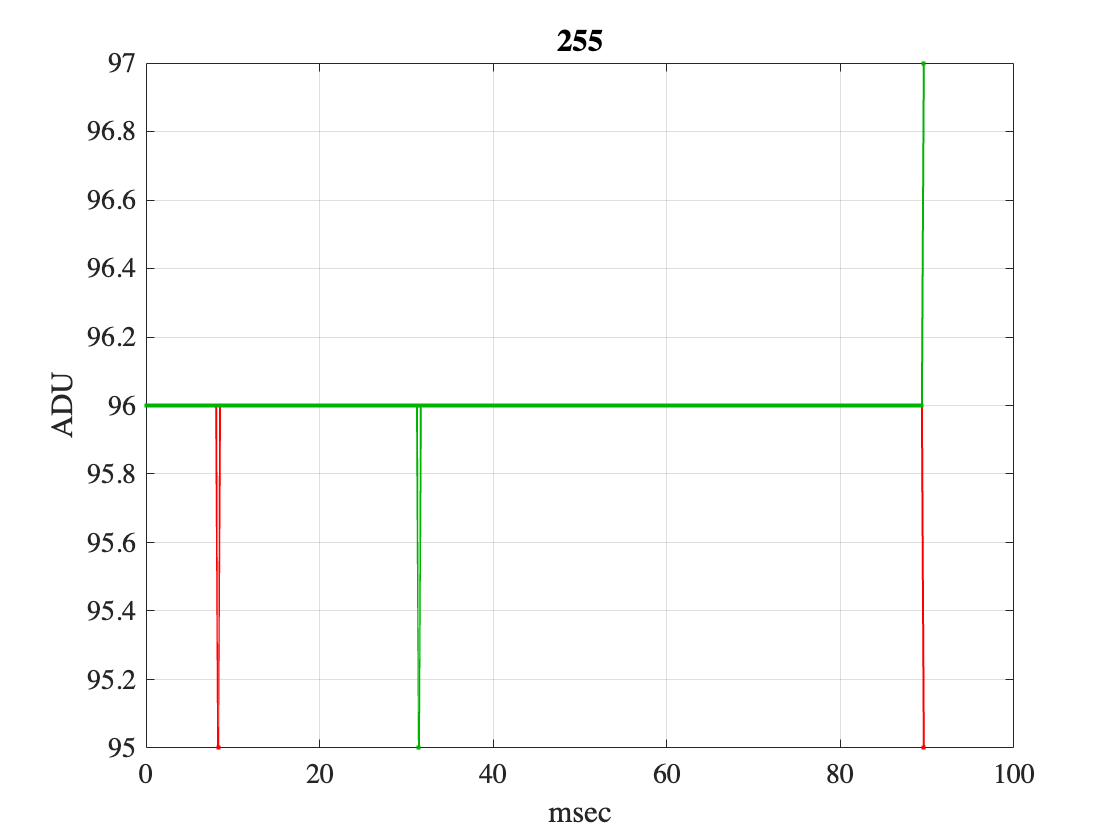

R5 = 1999; % ohms measured with dmm
R6 = 1000; % ohms
pwm = (50:5:255)'; % not expecting change below 68
writeline(ard, 'p 0'); pause(1); % extra settling time
v317 = zeros(size(pwm)); % allocate memory for voltage readback
noise = v317;
tic; % start a timer
for i=1:length(pwm)
    writeline(ard,sprintf('p %d',pwm(i)));
    runOnce = true; 
    oscope2; % --> new data
    title(num2str(pwm(i)));
    v317(i) = mean(data(:,1)) / 1023 * vref * (R5+R6)/R6; 
    noise(i) = std(data(:,1)) / 1023 * vref * (R5+R6)/R6;
end

toc  

Elapsed time is 26.132728 seconds.


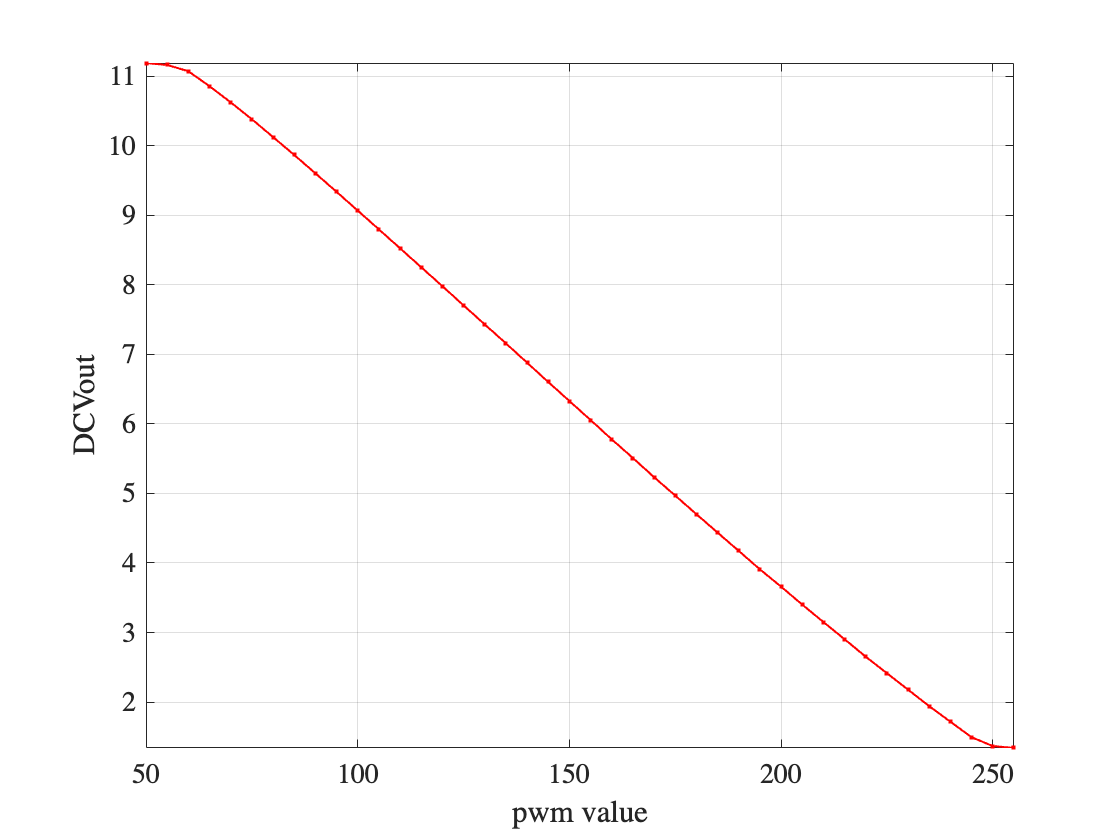

plot(pwm, v317, '.-'); 
xlabel('pwm value'); ylabel('DCVout'); grid; axis tight;

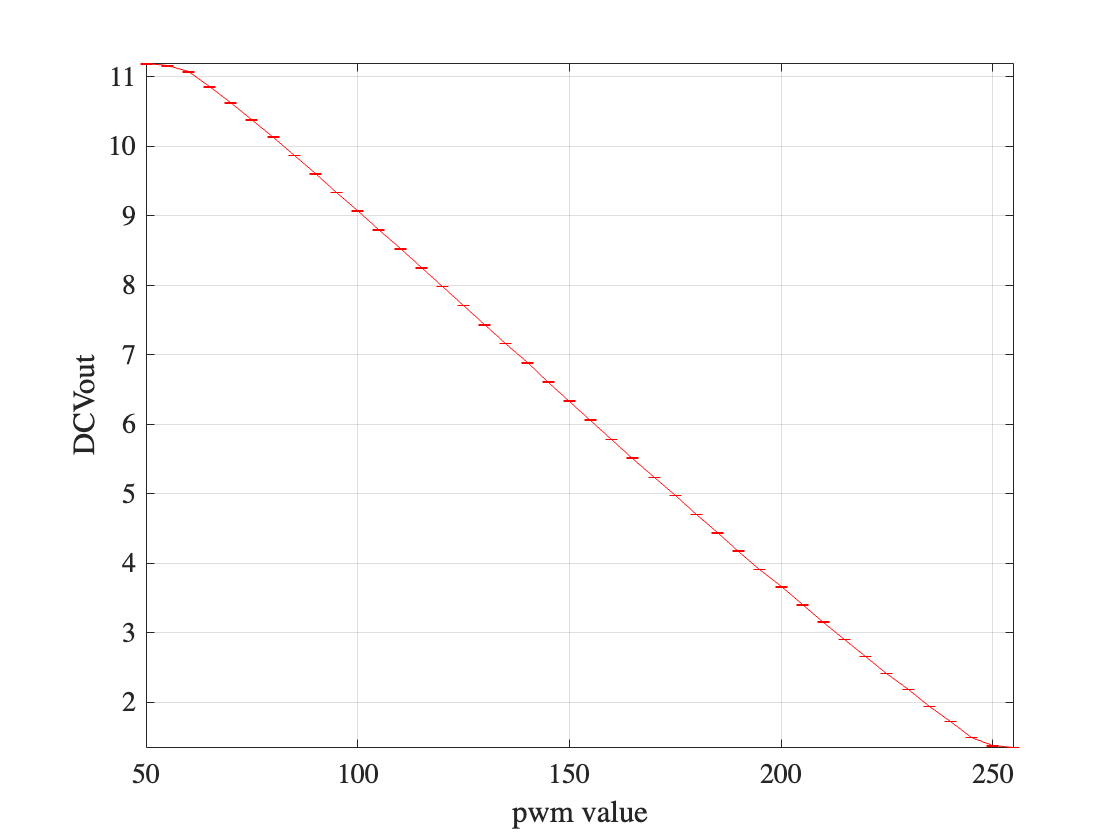

errorbar(pwm,v317,noise);
xlabel('pwm value'); ylabel('DCVout'); grid; axis tight;

        Figures 8 & 9. Oscope animation and mean readback Vout vs. PWM values.

I sometimes noticed noise around the 4th frame, PWM = 70 (that's why I added the `title` line to the code). I suspect one of the transistors is trying to decide whether to turn on and is at an unstable threshold. 

### Adjusting $R_E$

Recall when we initially built the LM317 circuit, R1 was chosen to maximize the usable range of R2. R1 defines the slope of the voltage vs. R2 curve. Too steep and we run out of Vin and saturate before reaching maximum R2, and too shallow and the maximum output voltage is reduced. Likewise, adjust $R_E$ to control the slope of Fig. 9. Too shallow and we won't reach minimum voltage, too steep and we get there before PWM = 255. After adjusting $R_E$ to achive the curve in Fig. 9, I turned off power and `writeline(ard, 'p 0');` to shut the emitter transistor, and measured $R_E$ = 3.421K$\Omega$, so the trim pot is set ~2.4k. That's quite close to expectation. The maximum voltage on $R_E$ ~ Vref - 1.2V for two series $V_{BE}$'s ~ 3.5V. To generate a shunt current ~1mA, $R_E$ ~ 3.5V/1mA ~ 3.5k. 

## Soldering

Convinced that it works, and that adjustments can easily be make later to the $R_E$ pot, I suggest soldering the circuit before final calibration and characterizations. Normally an engineer would be wise to leave the prototype intact and solder a copy from new parts. That way when the soldered circuit fails to work (I intentionally said "when"), you can use the working prototype to help troubleshoot. But since I don't have enough transistors in the kit to do this, I carefully removed one componenent at a time and soldered it onto the perforated board, checking off every connection I made on my drawing of the schematic. You may wish to sketch a parts layout diagram first. Here's what my soldered board looks like. 

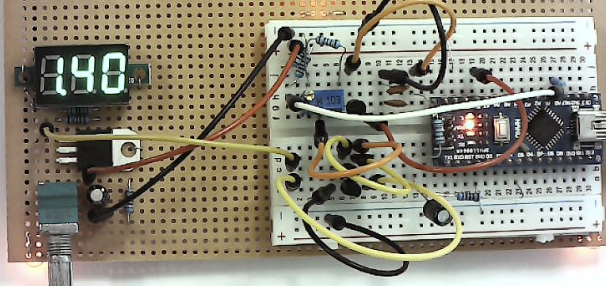 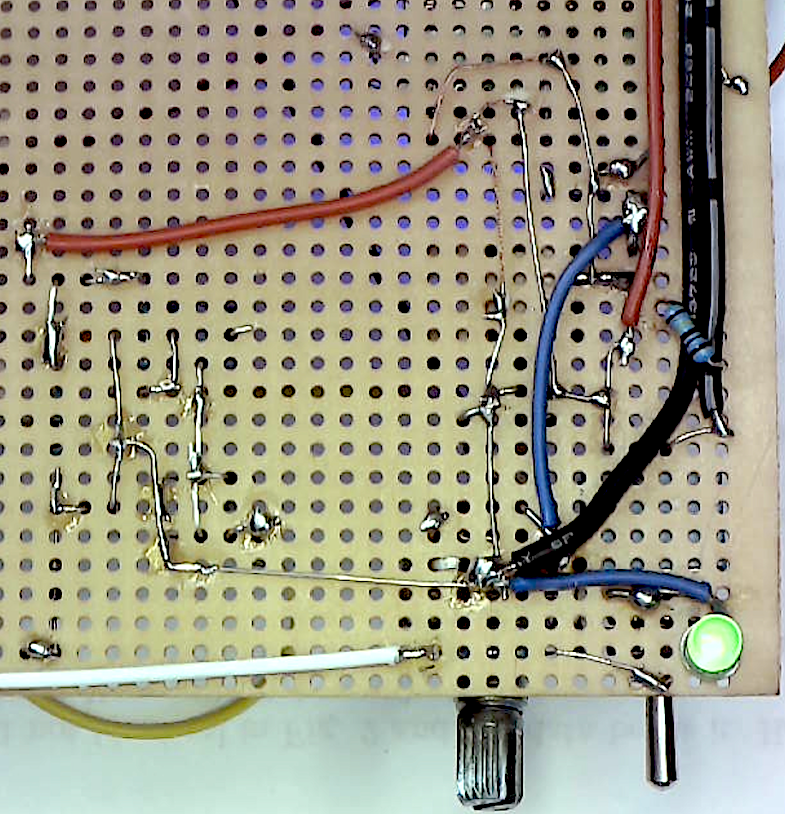

    Figure 10. Top and bottom view of soldered circuit board.

The underside of the board is flipped left-right from the top view. The PWM filter is on the far left, to its right the emitter follower and current mirror, and to the right of the long vertical ground wire is the previous LM317 circuit and 3-digit display. The PWM filter input is soldered to a blue jumper wire that reaches to D5. The current mirror collector and R2 are each soldered to yellow jumper wires that can connect using any common column of the solderless breadboard (lower column 1 above). This gives us flexibility to e.g., easily disconnect the shunt circuit, or use it with our function generator. R5 & R6, the voltage divider resistors remain on the breadboard (top left). 

In the prototype, Q1's collector was connected to the Arduino's 5V pin, and in prior versions of this circuit, I soldered a jumper wire to do this. However, I've also occasionally later forgotten to reconnect this jumper and wasted troubleshooting time rediscovering the error. Once while redrawing the schematic, I realized Q1's collector could instead connect to the switched 12V supply on the bottom of the board, as shown in Fig. 10B with the horizontal red wire to +12 at the 3-digit voltmeter. Think about how an emitter follower works: the emitter "follows" the base, $V_E = V_B-.6V$. The collector just has to be more than $V_B$ and capable of sourcing $\beta*i_B$ of current. Q1 will have to dissipate a little more power when connected to 12V. How much? Worst case for $I_{Mirror} = 1mA$, the emitter's voltage is ~ `vref-`.6V ~ 4V, so $P_{T1} = (12-4)V * 1mA = 8mW$, and the transistor's datasheet says its safe for >100mW, so it's far from overheating. Arduino's 5V source *was *more convenient for breadboarding because 12V isn't available on top, but 12V is more convenient on the bottom where Arduino's 5V isn't accessible. I rechecked calibration after this change, and the data was identical. Revised schematic is below. Drawing schematics not only documents our thoughts and constructions. They can also help us to think and discover new solutions. 

    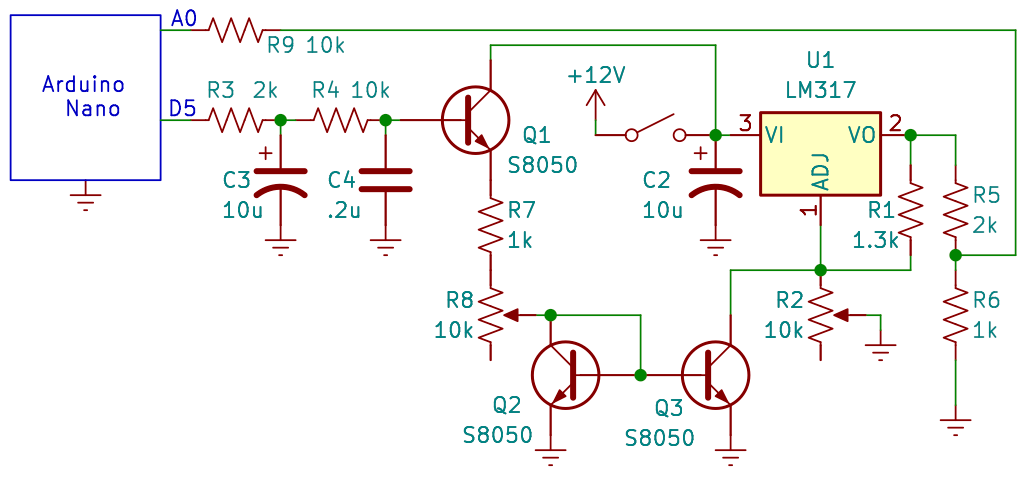

        Figure 11. Final controller circuit, with emitter follower connected to 12V. Note R3 = 2k, Q1-3 = 2N2222 or similar NPN BJT.

After careful visual inspection, testing a few PWM values, and debugging as necessary, repeat the measurements for Fig. 9.  

## Noise

An important characteristic of a DC power supply is its noise, the AC or time-varying signal superimposed on the average DC level. We worked hard to design a PWM filter that produced clean DC with < 1ADU of noise -- but is that low enough? What if the emitter follower or current mirror amplified the noise -- keep in mind our analysis of these circuit elements was mostly focusing on their DC transfer functions, and not their sensitivity or gain at higher frequencies. We can measure noise with our DMM set to AC or mVAC. We can also use the Arduino. The following function measures the AC components of time series (like `data`) similar to what an RMS AC DVM measures (although in units of ADU if the input waveform is in ADU). Save it in your PATH. 

We've used this formula earlier -- its just easier to use a function. Let's measure the noise, which we might expect to be maximum at PWM = 128: 

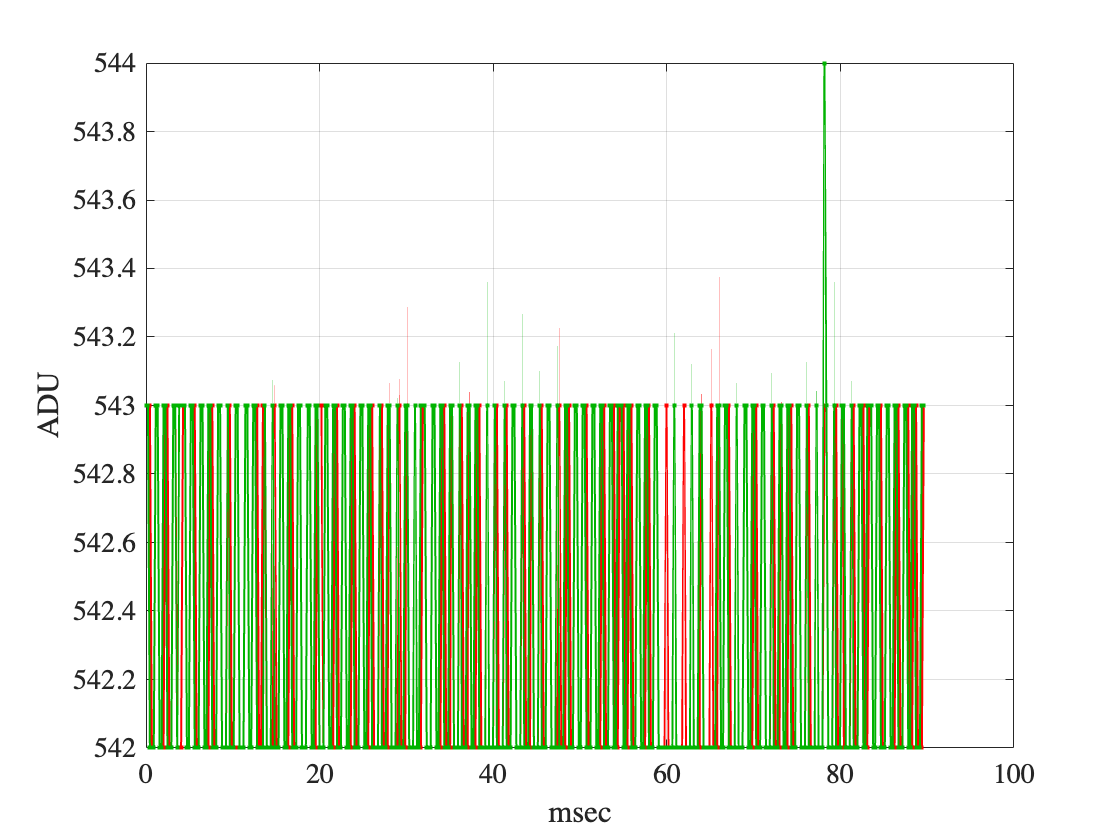

ans =     0.4909    0.4923


 writeline(ard, 'p 128'); pause(.5); 
 runOnce = true; oscope2; mrms(data)

        Figure 12. Noise at PWM = 128 is 2 ADU peak-to-peak = .73ADU RMS. 

Repeating a few times gives a sense of the standard deviation, or the "noise of the noise". Converting to volts: 

 ans * vref / 1023

ans =     0.0023    0.0023


My DVM measures 3-4mVAC on A0 and 14mVAC on the LM317 output (before the voltage divider), not too different from MATLAB (considering we're looking at a computed value from signals of amplitude ~ 1-2 ADU). What's the spectrum of this noise? The DMM can't answer that, but MATLAB can:

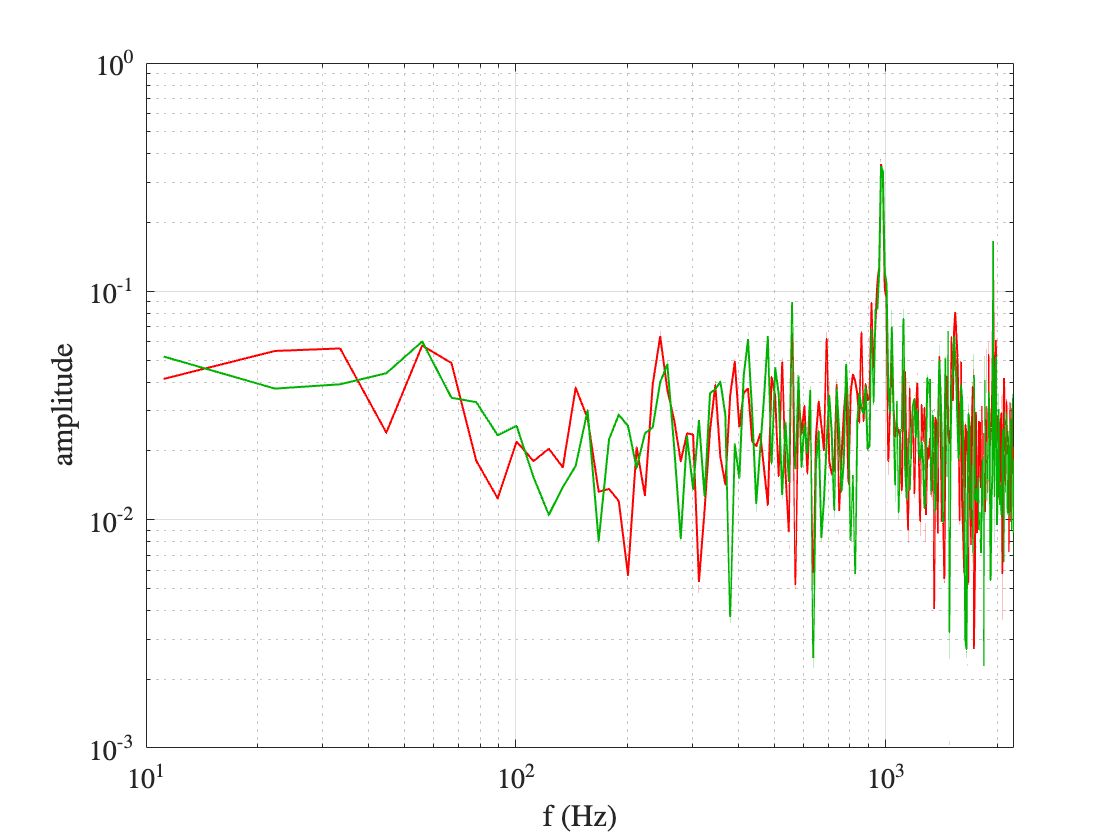

sr = length(data)/dt*1e6; % sample rate (#/sec)
aspectrum(data, sr);

        Figure 13. Amplitude spectrum of the noise in Fig. 12. 

Although only measurable with 1 significant figure with our DVM and ~ 1ADU in the time series, in the frequency domain, the PWM signal stands out like an enormous mountain -- we have no doubt from where this 970Hz signal comes from! The time domain (Fig. 12) doesn't suggest strategies to reduce the noise as does the same data displayed in the frequency domain (Fig. 13). We could shift the corner of a PWM filter, trading off some settling time for steeper attenuation. We might also add capacitance elsewhere to act like inertia, analogous to additional mass on a pendulum reduces high frequency vibrations. E.g., at the other end of the circuit, how might a capacitor between A0 and ground shunt high frequencies to to ground? What values should we try? We don't have many C's to choose from in our kits. Too big risks slow time constant and long settling times, too small won't have significant effect. The impedances of a few of the C's in our kit at the PWM frequency are:

fprintf('%.1g\t', abs(zc([100e-12 100e-9 4.7e-6 47e-6],970)))

2e+06	2e+03	3e+01	3	

The first one, 100pF has 2 megohm impedance that's likely too high to divide a voltage or shunt significant current. The 100nF is 2kohms, similar to impedances we're using, so it's a good place to start. The results with 100nF between A0 and ground are: 

The amplitude of the 970Hz peak in the spectrum dropped from .53ADU (in Fig. 13) to 0.39 Thus this C offers a 36% attenuation of the noise, but might it have other negative effects, e.g., on rise times or future phase shift measurements? Rise times are easy to check now by eyeballing the `oscope2` displays and measuring the RMS amplitudes: 

I left enough time between each command to guarantee convergence at the prior value, and observed no apparent settling time problem. Keep it!!

## Calibration

Our goal now is to create a MATLAB command, maybe call it `setVoltage(volts)` for which the power supply responds accordingly. We could use the data in Fig. 9 as a look-up table, but let's first try a more compact way to estimate a `volts2pwm` converter using least squares fit: 

Figure 9 looks pretty linear if we ignore both ends, so we can try N = 1. How to cut the flat end points from the curve fit? After some trial-and-error: 

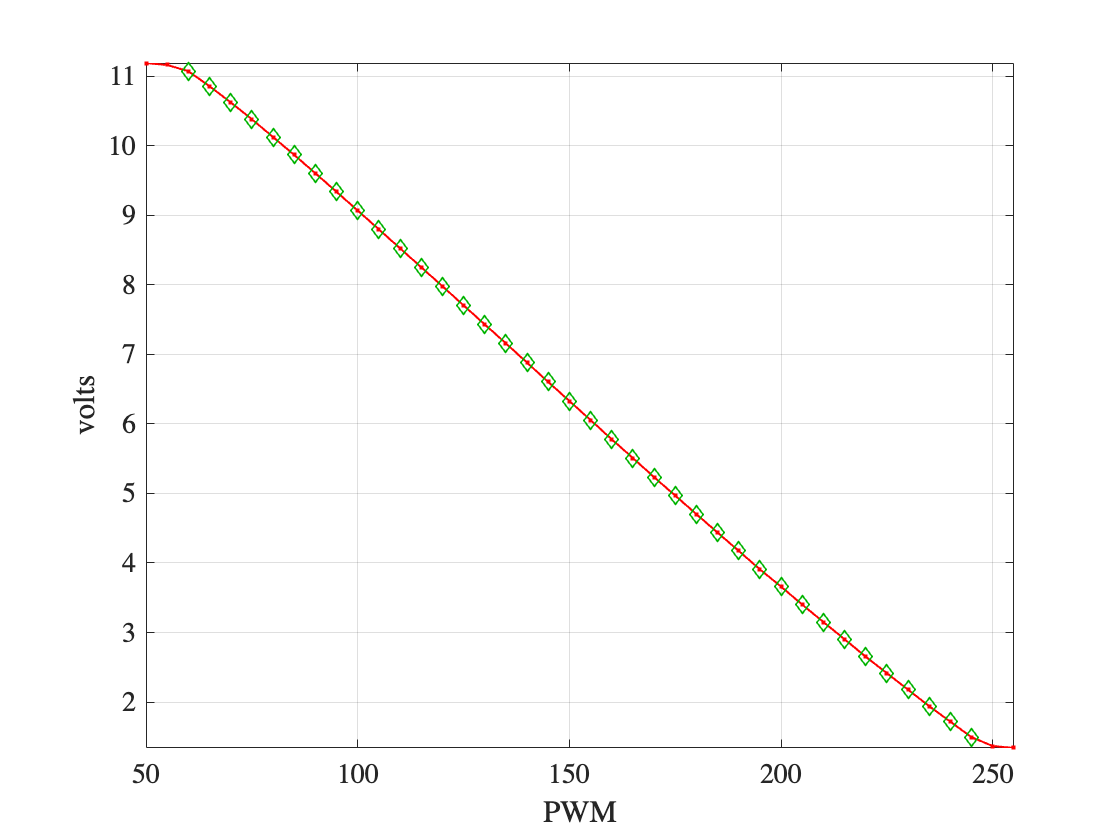

indx = v317 < .99 * max(v317) & v317 > 1.1 * min(v317); % boolean
plot(pwm, v317, '.-', pwm(indx), v317(indx),'d')
axis tight; grid; xlabel('PWM'); ylabel('volts')

        Figure 14. Data points for least squares fit shown as green diamonds.

`p = polyfit(pwm(indx), v317(indx), 1)` is a polynomial we could use to predict a voltage (y value) from any given PWM (x value), but that's the opposite of what we seek, so ... we could do algebra, or just flip `polyfit`'s arguments to do we want. Then we can use `polyval` to verify the model:

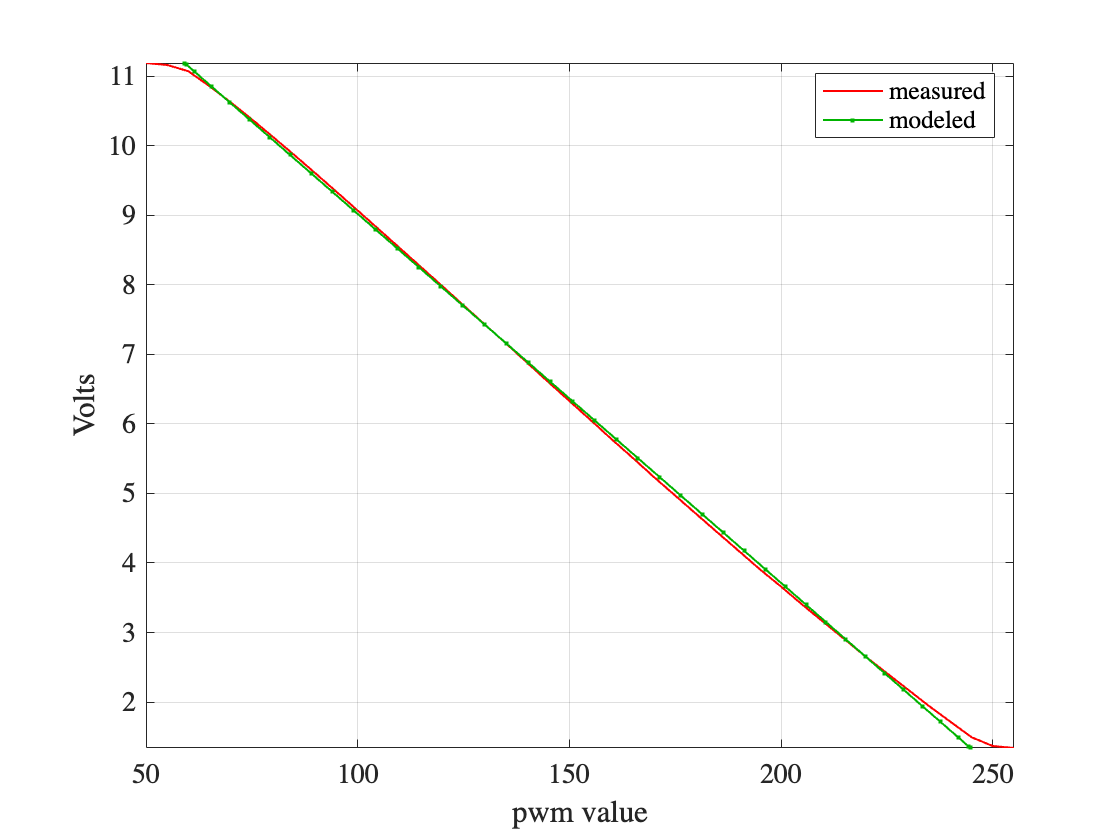

pv = polyfit(v317(indx), pwm(indx), 1); % flipped x and y from Fig. 9
pwmModel = polyval(pv,v317); % model the polynomial
plot(pwm, v317, pwmModel, v317, '.-')
xlabel('pwm value'); ylabel('Volts'); 
legend('measured','modeled','location','best')
axis tight; grid

        Figure 15. Linear model of the data. 

A difference plot is useful here because the dynamic range of voltage makes it hard to resolve the pattern of the much smaller errors. A difference plot essentially *rotates* Fig. 15, making the slope horizontal. The residual suggests a 3rd order polynomial maybe a better fit, so let's try it too:

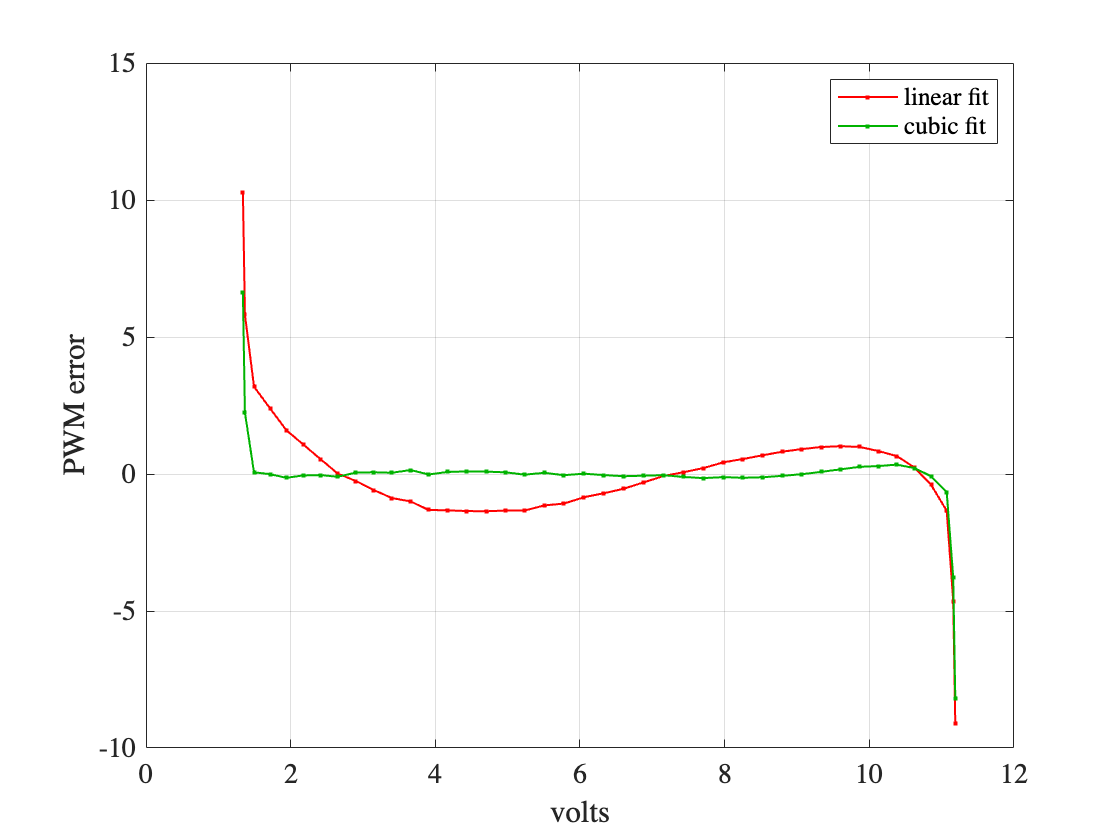

err = pwm - pwmModel;
pv3 = polyfit(v317(indx), pwm(indx), 3); % flipped x and y from Fig. 9
pwmModel3 = polyval(pv3,v317);
err3 = pwm - pwmModel3;
plot(v317, [err err3], '.-'); grid;
xlabel('volts'); ylabel('PWM error');
legend('linear fit','cubic fit')

        Figure 16. Difference or error plot for 1st and 3rd order polyfit. 

Not surprising that the fit is bad at both ends, where the data (and transistors) plateau. But almost everywhere the 3rd order fit is a closer model of the data, with every PWM error << 1 unit between the plateaus.

Let's save this data to compare with later models -- to write it to file `pwmcaldata.mat` in your current directory:

pwd % print working directory

ans = '/Users/brian/Documents/csuci/2025/f25/310f25/week10 -- LM317Automation'

% save pwmcaldata pwm v317

### pwm = volts2pwm(volts, arduino)

What are the polynomial coefficients in `pv3? `

pv3

pv3 =    -0.0491    1.0087  -24.9804  280.1577


We should be concerned about significant figures and "balancing" of the polynomial coefficients. Because the data in Fig. 14-15 are far from the origin, the polynomial coefficients are widely distributed which can lead to round-off errors. But in our case we have to round PWM to 3 significant figures, i.e., 0-255, so it's not an issue. (If you want more significant figures, execute` >> format long; pv3, format short). `Here's a function that converts a desired voltage to its corresponding PWM value, does bounds checking, and I added a second input argument to *make *it happen (why not -- it was easy):

Make sure to substitute your polynomial coefficients into `pv`. Every power supply will have unique optimal calibration parameters. This is another example of negative feedback -- your transistors likely have different $\beta$'s than mine, your resistors and pots are adjusted differently. Your LM317's Vref is unique, as is your Arduino's Vref. "Feeding back" the measurered v317 with `polyfit` results in coefficients that minimize error in your output. Save your function in MATLAB's PATH and verify it's there with `>> which volts2pwm`.

## Final testing and characterization

We should test a few values, e.g., does `volts2pwm(5, ard)` set the LM317 to around 5V? But let's use automation to test more comprehensively:

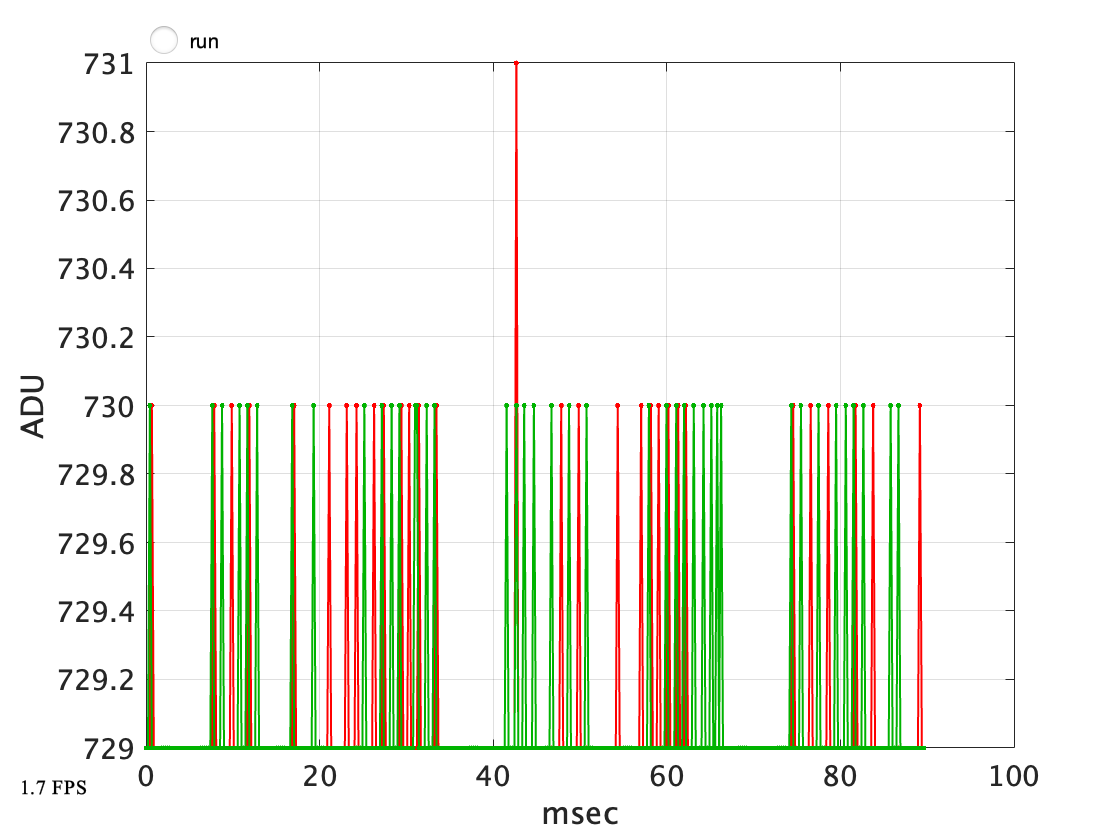

vset = linspace(1.5,10.2,50)'; % try to set these 50 voltages
meanV = zeros(size(vset)); stdV = meanV; % allocate result vectors
volts2pwm(vset(1), ard); pause(1); % extra settling time
tic; 
for i = 1:length(vset)
    volts2pwm(vset(i), ard); 
    runOnce = true; oscope2; 
    meanV(i) = mean(data(:,1));
    stdV(i) = std(data(:,1));
end

toc

Elapsed time is 28.841613 seconds.


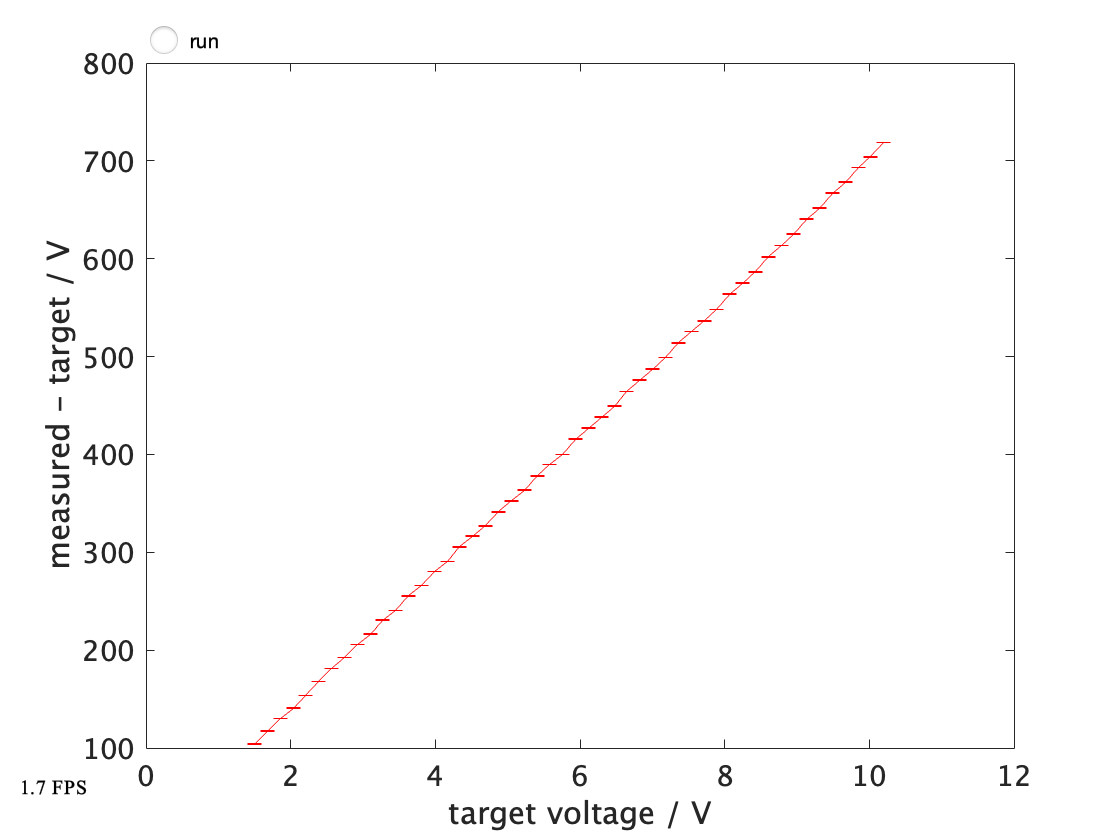

err = meanV - vset;
errorbar(vset, err, stdV); xlabel('target voltage / V'); ylabel('measured - target / V');

        Figure 17. Difference plot -- but what went wrong?

... 

Demonstrating another useful built-in MATLAB function, `errorbar`. The data looks tight but the difference (y-values) are gawd-awfully big!! Why?? .... Inconsistent units! `vset` is in volts and `meanV` (and `stdV`) are in ADU. We don't need to collect new data, just fix what we have (but careful to only execute the following lines once since the variables aren't renamed -- I added Section Breaks to the .mlx file and Run Section carefully):

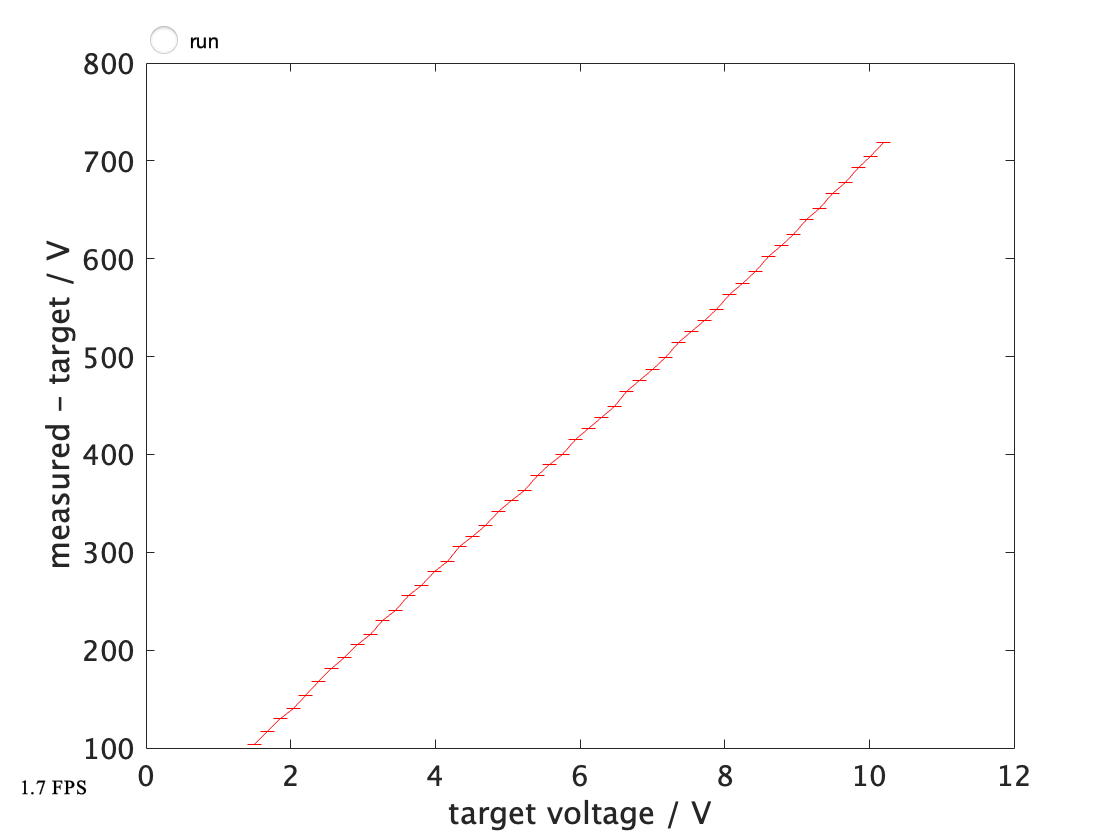

meanV = meanV * vref / 1023; 
stdV = stdV * vref / 1023;
errorbar(vset, err, stdV); xlabel('target voltage / V'); ylabel('measured - target / V');

        Figure 18. Still bugs ... 

The errorbars got smaller, but why no change in the y-axis? ..... Ahhh, plotting err and forgot to recompute it. But there's still another bug ... forgetting the voltage divider R6 and R7

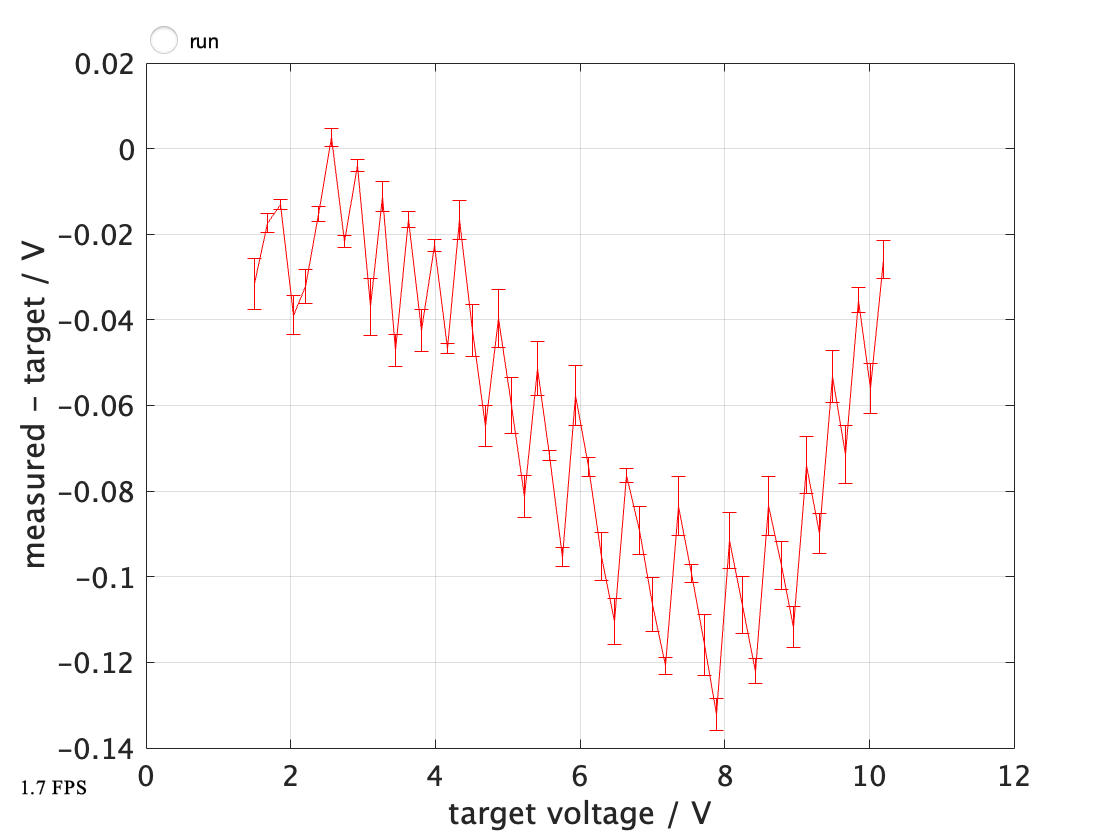

meanV = meanV * (R5+R6) / R6; % now its in volts
stdV = stdV * (R5+R6)/R6; 
err = meanV - vset;
errorbar(vset, err, stdV); 
xlabel('target voltage / V'); ylabel('measured - target / V');
grid;

        Figure 19. Error plot, error bars represent standard deviation of the 400 measurements at each voltage.

This curve demonstrates several phenomena. 

- The Arduino controlled LM317 generates voltages within <150mV of its target from 1.5-10V. 

- The error is largely systematic -- this curve isn't random, so a look-up table, higher order polynomial, or other algorithm might predict the systematic effects better and be more accurate (if that were necessary, and if the errors were *stationary*).

- The jumps might correlate with aspects of the PWM algorithm -- i.e., a clock likely produces pulse widths with discrete durations. 

- ...

But don't let my constant squeezing of data and sniffing for improvements let you lose sight of the forest for the trees. WE DESIGNED AND BUILT AN AWESOME COMPUTER-CONTROLLED DC POWER SUPPLY that ROCKS!!! 

## Conclusions

Hopefully this activity has improved your appreciation and understanding of electronic design, abstraction with circuit "building blocks", prototyping and soldering, testing and debugging, and the enormous power of automating measurements and analyses. In writing this document, I repeated calibration loops, consisting of 50 calls to `oscope2`, maybe 25 times. Each oscope call measaured 800 data points, so the results presented here are based on ~ 25 * 50 * 800 = 1 million measurements. Don't try that without automation!! That partially explains why the data is so clean. Arduinos have a good ADC, and lots of averaging reduces noise. 

Although I stated at the beginning that my goal was to make a function, `setVoltage(volts)`, I'm perfectly content using `volts2pwm(volts, arduino)` instead. It's name reminds me how it works and it solves a potential problem with scope of Arduino's serial port object. `ard` has to be shared by the workspace and any function that needs it. If `volts2pwm` tried internally to connect to the arduino (by calling `serialport`), it would have failed because the port is busy. If we were doing "top-down" design [1], then renaming the function and changing its arguments could be problematic, as it could affect other code already written. Bottom up design gives us the freedom to decide to use `volts2pwm` as the power supply control interface, without changing anything else. 

The change we made to powering Q1's collector from 12V after prototyping with 5V, and the addition of a 100nF capacitor shunt on A0 even later in the process shows how design --> prototype --> build and characterize is not a linear process. Taking opportunities to improve system performance at each step can be a good (but potentially disruptive) practice. On the flip side, one has to be careful of unanticipated consequences of late changes. I suspect the 100nF capacitor shunting A0 will have to go when we measure function generator signals at high frequencies, but it reduces noise in the DC measurements that we're doing here. 

Automation is really useful in bootstrapping system designs. Each call to `oscope` measured another 800 data points, and we called it over and over -- sometimes in loops, sometimes manually. We used *all* this data, with `mrms` and/or visual confirmation of the waveforms and spectra. Without an automated engine, our paths would have been inconceivably tedious, practically impossible -- so we would have had to find other paths. Nevertheless, you may encounter engineers reluctant to automate early and instead argue that its additional complexity hinders development. "Automate later" they argue. I am convinced that automating early ensures the system is much more rigorously tested and debugged earlier, and fewer disruptive changes will be discovered or required later to enable automation and other "add on" features. You may find the best way to convince such folks is by doing it -- quietly implementing automation and letting the results speak for themselves.

**What other lessons can you enumerate? **

- From R's and C's we built filters to turn PWM signals into clean DC voltages. Transistors changed impedances. Resistors transduced (converted) voltages into currents. A current mirror shunted the LM317's R2, effectively "turning it down" without physically rotating its knob The mirror also served another key function: it isolated the Arduino from the high (lethal to an Arduino) voltage at R2.

- Understanding a schematic like Fig. 18 without knowing its history, origins, etc. is dauntingly difficult. You have to train yourself to imagine modular boundaries (that you learn to recognize). Just as this sentence would make little sense if read aloud as a sequence of individual letters, looking at the schematic as a hodge-podge of R's, C's, Q's,  doesn't make much sense to anyone. The letters are separated by spaces, and good schematics likewise have cues to help you parse the modules. But practice and memorization play key roles in recognizing filters, followers, mirrors, voltage dividers, etc. Good news is that there aren't *that* *many* building block circuits that are repeated over and over. 

- Least-squares fit (MATLAB's `polyfit`) gave us parameters of a model to convert from one variable (volts) to another (PWM value). 

- `errorbar()` is a neat MATLAB function and difference plots help us visualize especially small errors.

- Persevere ... I deliberately included Figs. 17-18 even though they are wrong. I usually don't publish my mistakes, but that can leave a reader with the false sense that I (and most professionals) don't make many. What makes me a good scientist/engineer is that I make mistakes *a lot*, but have more practice and efficient strategies for finding and debugging them. 

**What can you add to this list?**

Although this circuit was designed with one purpose of controlling the LM317 voltage, it turns out to be a general "building block" which we'll repurpose or recyle to control the frequency of our function generator kit! In software we often deliberately seek to build modular code to facilitate its repurposing and reuse. Although that wasn't an explicit goal here, it turns out we achieved it. More to come ... 

**More questions: **

- How might an op-amp *improve* this controller? What would it replace, and how/why would it function better? Why didn't we use an op-amp?

## References 

[1] [https://en.wikipedia.org/wiki/Top-down_and_bottom-up_design](https://en.wikipedia.org/wiki/Top-down_and_bottom-up_design) 

[2] [https://www.st.com/resource/en/datasheet/lm317.pdf](https://www.st.com/resource/en/datasheet/lm317.pdf) 

[3] [https://en.wikipedia.org/wiki/Current_mirror](https://en.wikipedia.org/wiki/Current_mirror) 

[4] [https://en.wikipedia.org/wiki/Common_collector](https://en.wikipedia.org/wiki/Common_collector) (emitter follower)